load('i1data_nec.mat','cxfdata')

% cxfdata is 24x36 (patch x wavelength)
% manually copy-n-paste from Excel to Matlab

patch_order_in_cxf = [1 10 11 12 13 14 15 16 17 18 19 2 20 21 22 23 24 3 4 5 6 7 8 9];
spec_order = 380:10:730;

patch_row_to_id = [[1:24]' patch_order_in_cxf'];
patch_row_to_id_sorted = sortrows(patch_row_to_id,2);
patch_id_to_row = [patch_row_to_id_sorted(:,2) patch_row_to_id_sorted(:,1)]

patch_id_to_row =      1     1
     2    12
     3    18
     4    19
     5    20
     6    21
     7    22
     8    23
     9    24
    10     2


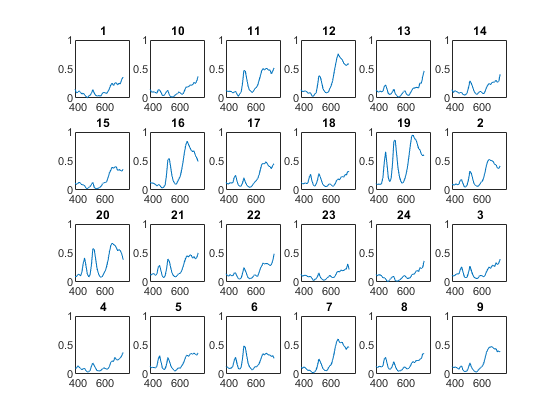


specdata = cxfdata(patch_id_to_row(:,2),:);

% check the original data
clf
hold on
for i=1:24
    subplot(4,6,i)
    plot(spec_order,cxfdata(i,:))
    axis([380 780 0 1])
    title(patch_order_in_cxf(i))
end

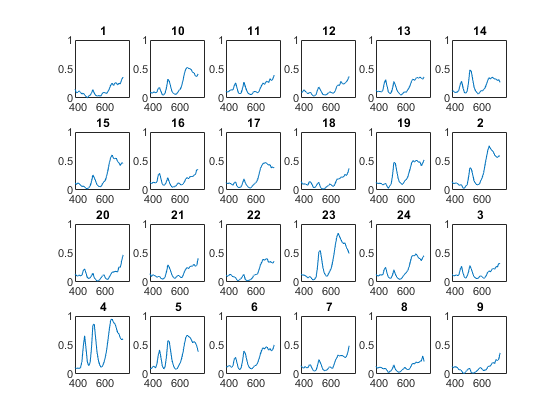


clf
hold on
for i=1:24
    subplot(4,6,i)
    plot(spec_order,specdata(i,:))
    axis([380 780 0 1])
    title(patch_order_in_cxf(i))
end